load face_detect.mat
% vectorize the test images 
face_number = randi(size(faces_test_easy,3))

face_number = 27

vectorized_images_train = reshape(faces_train, [size(faces_train,1)*size(faces_train,2),size(faces_train,3)]);
vectorized_images_test = reshape(faces_test_easy(:,:,face_number), [size(faces_test_easy(:,:,face_number),1)*size(faces_test_easy(:,:,face_number),2),size(faces_test_easy(:,:,face_number),3)]);

approx_num_train = 10;
approx_num_test = 1;

% create a covariance matrix
mean_centered_data_train = mean_centered(vectorized_images_train);
mean_centered_data_test = mean_centered(vectorized_images_test);

% SVD
[largest_eigenvalues_train, largest_eigenvectors_train] = single_value_decomp(mean_centered_data_train, approx_num_train);

eigenvalues =    1.0e+05 *

    1.0158
    0.7629
    0.5339
    0.4103
    0.3546
    0.2887
    0.2633
    0.2485
    0.2277
    0.2266


lambda =    1.0e+05 *

    1.0158
    0.7629
    0.5339
    0.4103
    0.3546
    0.2887
    0.2633
    0.2485
    0.2277
    0.2266


v =     0.0016    0.0009    0.0048    0.0009    0.0053   -0.0058    0.0020   -0.0043   -0.0013    0.0053
    0.0017    0.0009    0.0050    0.0010    0.0054   -0.0058    0.0024   -0.0044   -0.0013    0.0051
    0.0018    0.0008    0.0053    0.0010    0.0055   -0.0056    0.0031   -0.0044   -0.0013    0.0046
    0.0019    0.0008    0.0056    0.0012    0.0056   -0.0056    0.0036   -0.0045   -0.0014    0.0041
    0.0021    0.0007    0.0058    0.0013    0.0057   -0.0055    0.0040   -0.0045   -0.0014    0.0036
    0.0022    0.0007    0.0060    0.0014    0.0057   -0.0056    0.0042   -0.0044   -0.0015    0.0035
    0.0022    0.0007    0.0061    0.0014    0.0058   -0.0057    0.0042   -0.0044   -0.0015    0.0037
    0.0023    0.0007    0.0061    0.0014    0.0058   -0.0058    0.0043   -0.0045   -0.0014    0.0038
    0.0023    0.0006    0.0062    0.0014    0.0059   -0.0058    0.0044   -0.0046   -0.0015    0.0038
    0.0024    0.0006    0.0062    0.0015    0.0060   -0.0058    0.0045   -0.0046   -0.0

[U_test,S_test,V_test] = svd(mean_centered_data_test,'econ');

Reduced_Train = largest_eigenvectors_train'*vectorized_images_train;
Reduced_Test = U_test'*vectorized_images_test;

w_test = repmat(Reduced_Test,approx_num_train,size(Reduced_Train,2));
difference = w_test - Reduced_Train;
distances = (sum(difference.^2)).^.5;
minDis = min(distances)

minDis = 1.7433e+04

index = find(distances==minDis,1) 

index = 25

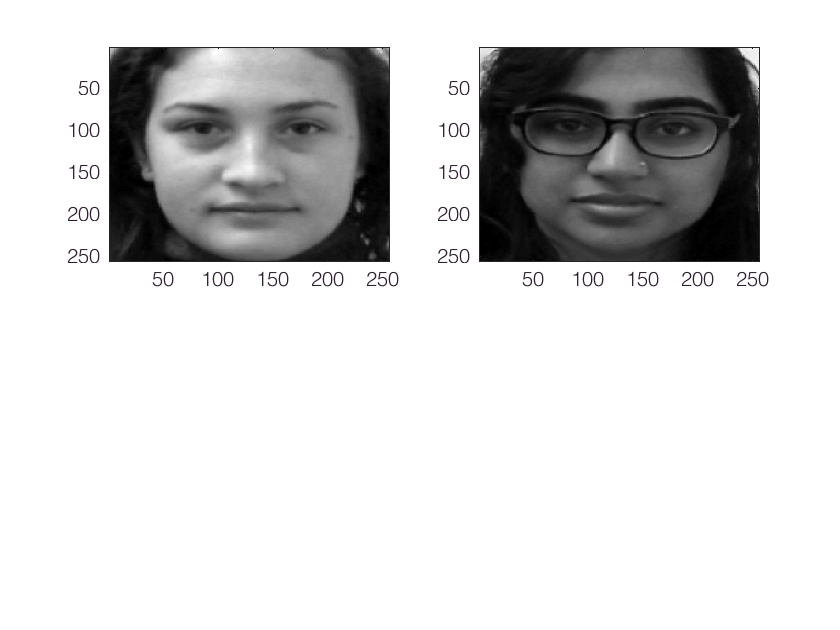

hold on;
subplot(2,2,1);
imagesc(faces_test_easy(:,:,face_number)); colormap('gray')
subplot(2,2,2);
imagesc(faces_train(:,:,index)); colormap('gray')
hold off;

**Weights of Faces**

Index the difference 

Creating mean centered data function 

function mean_centered_data = mean_centered(reshaped_image)
    o = ones(1,size(reshaped_image,2));
    m = mean(reshaped_image,2)*o;
    mean_centered_data = reshaped_image-m;
end

Single Value Decomposition's largest eigenvalues and eigenvectors

function [lambda, v] = single_value_decomp(faces,num)
    [U, S, V] = svd(faces, 'econ');
    eigenvalues = diag(S) 
    lambda = eigenvalues(1:num)
    v = U(:,1:num)
end